### 1.3 Continuous Wavelet Decomposition

clearvars; close all; clc;

fs = 250;           % Sample frequency
N = 3000;           % Data length  
t = (-N:N)/fs;      % Time scale for wavelet

s_values = 0.01:0.01:2; % Scale resolution for wavelets

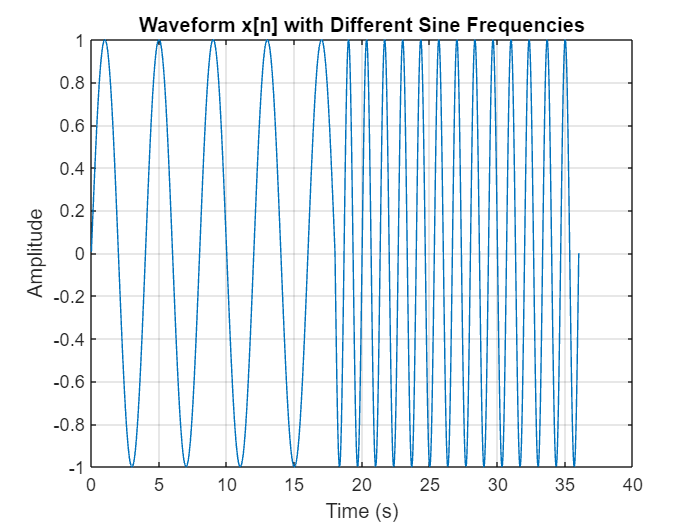

% Define the total number of samples: 3N
n_total = 3 * N;

% Initialize the signal array x[n]
x = zeros(1, n_total);

% Generate the first segment: 1 <= n < (3N)/2
for n = 1:(3 * N / 2) - 1
    x(n) = sin((1/fs) * 0.5 * pi * n);
end

% Generate the second segment: (3N)/2 <= n < 3N
for n = (3 * N / 2):(3 * N) - 1
    x(n) = sin((1/fs) * 1.5 * pi * n);
end

% Define the time vector corresponding to the signal
t_ = (0:n_total - 1) / fs;

% Plot the waveform
figure;
plot(t_, x);
xlabel('Time (s)');
ylabel('Amplitude');
title('Waveform x[n] with Different Sine Frequencies');
grid on;

% Initialize matrix to store convolution results
convolved_signals = zeros(length(s_values), length(x));
tau = 0;

% Loop over each scale and perform convolution
for i = 1:length(s_values)
    s = s_values(i);  % Current scale

    % Construct the scaled Mexican hat wavelet
    wavelet = mexican_hat_wavelt(t, s, tau);

    % Perform convolution of the signal with the wavelet
    conv_result = conv(x, wavelet, 'same');  % 'same' keeps the output size

    % Store the convolved signal
    convolved_signals(i, :) = conv_result;

    % % Plot the convolved result for each scale
    % figure;
    % plot(conv_result);
    % title(['Convolved Signal for Scale s = ' num2str(s)]);
    % xlabel('Time (samples)');
    % ylabel('Amplitude');
end

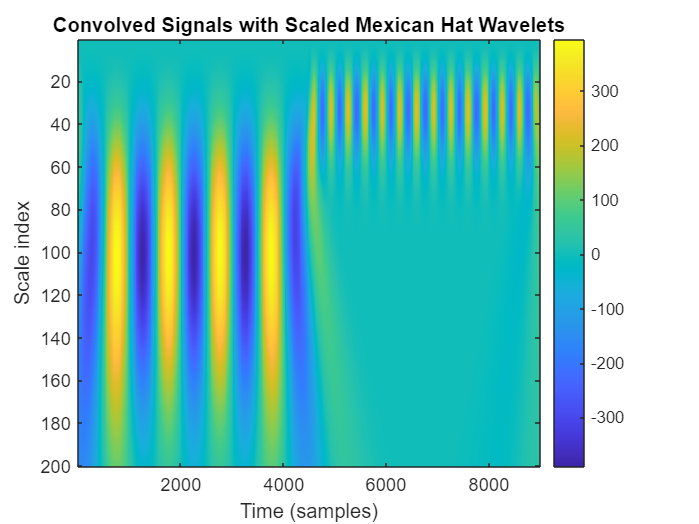

% Visualize the convolved results (e.g., as an image)
figure;
imagesc(convolved_signals);
colorbar;
xlabel('Time (samples)');
ylabel('Scale index');
title('Convolved Signals with Scaled Mexican Hat Wavelets');

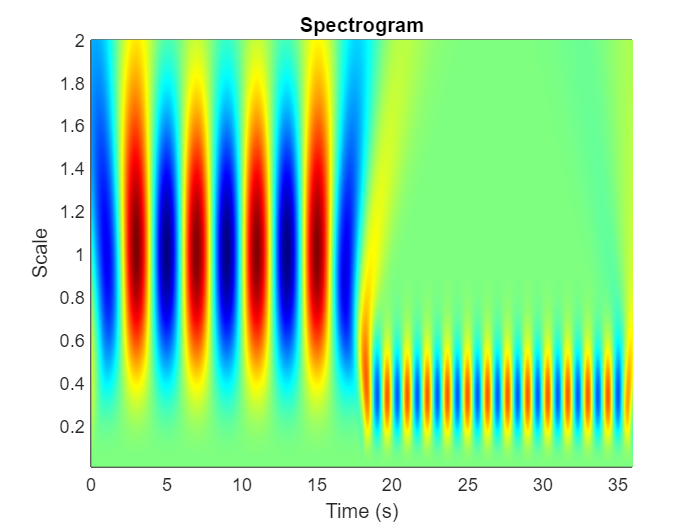

% Ploting the spectrogram
figure;
h = pcolor(t_, s_values, convolved_signals);
set(h, 'EdgeColor', 'none');
colormap jet
xlabel('Time (s)')
ylabel('Scale')
title('Spectrogram')

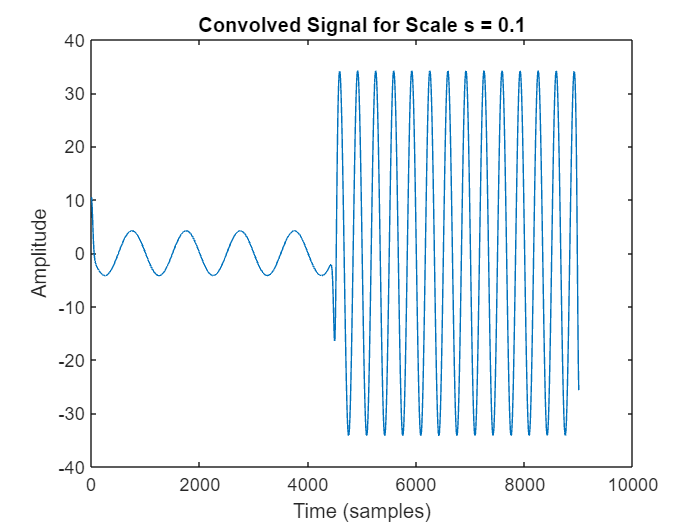

% Plot the convolved result for each scale (uncomment to view)
figure;
plot(convolved_signals(10,:));
title(['Convolved Signal for Scale s = 0.1']);
xlabel('Time (samples)');
ylabel('Amplitude');

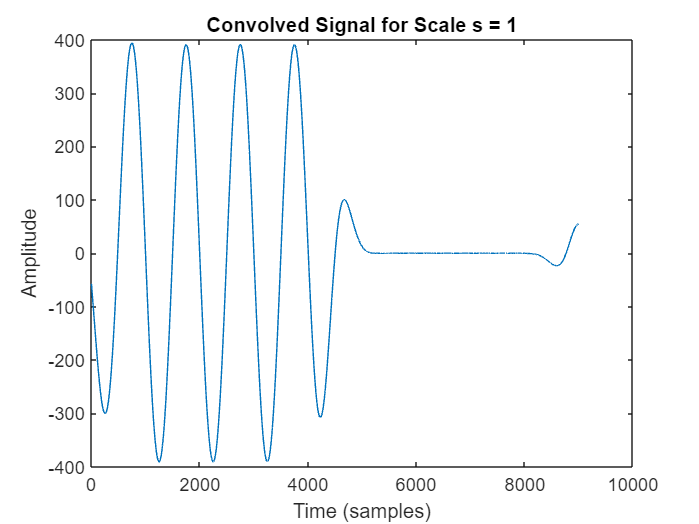


% Plot the convolved result for each scale (uncomment to view)
figure;
plot(convolved_signals(100,:));
title(['Convolved Signal for Scale s = 1']);
xlabel('Time (samples)');
ylabel('Amplitude');

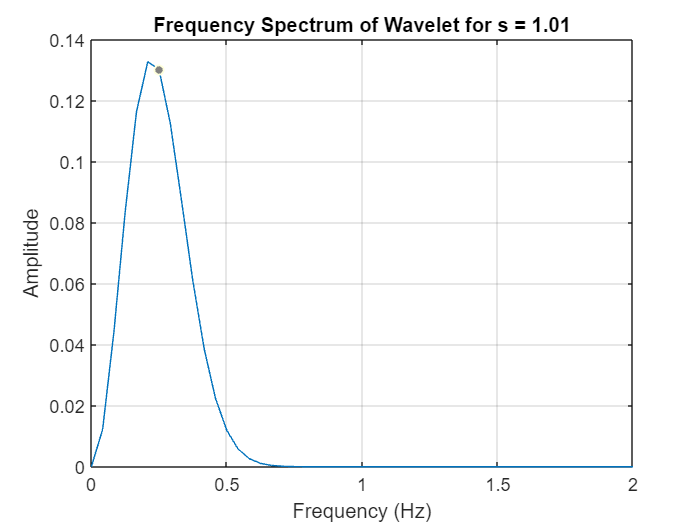

% Plot the spectra of s=1.01
wavelet_s_1 = mexican_hat_wavelt(t, 1.01, 0);

Fwavelt_s_1 = fft(wavelet_s_1) / length(wavelet_s_1);
hz = linspace(0, fs / 2, floor(length(wavelet_s_1) / 2) + 1);

figure; % Create a new figure for each FFT plot
plot(hz, 2 * abs(Fwavelt_s_1(1:length(hz))));
xlabel('Frequency (Hz)');
xlim([0 2]);
ylabel('Amplitude');
title(['Frequency Spectrum of Wavelet for s = 1.01']);
grid on;

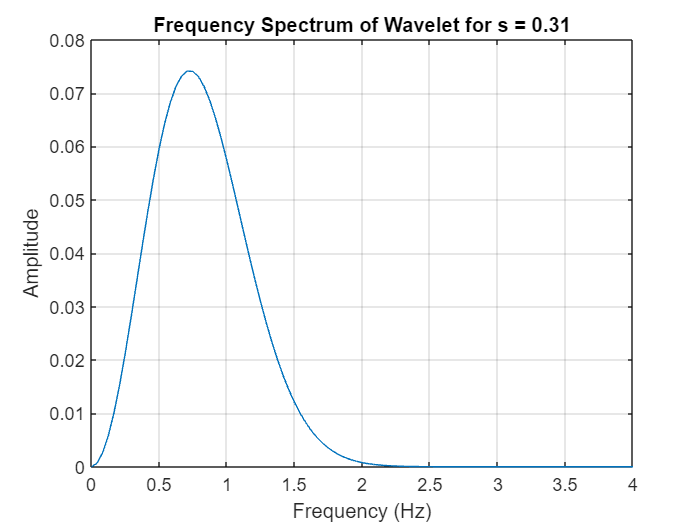

% Plot the spectra of s=0.31
wavelet_s_31 = mexican_hat_wavelt(t, 0.31, 0);

Fwavelt_s_31 = fft(wavelet_s_31) / length(wavelet_s_31);
hz = linspace(0, fs / 2, floor(length(wavelet_s_31) / 2) + 1);

figure; % Create a new figure for each FFT plot
plot(hz, 2 * abs(Fwavelt_s_31(1:length(hz))));
xlabel('Frequency (Hz)');
xlim([0 4]);
ylabel('Amplitude');
title(['Frequency Spectrum of Wavelet for s = 0.31']);
grid on;